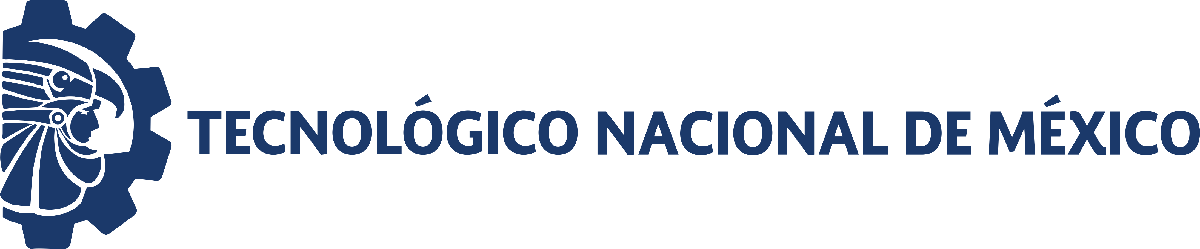                                 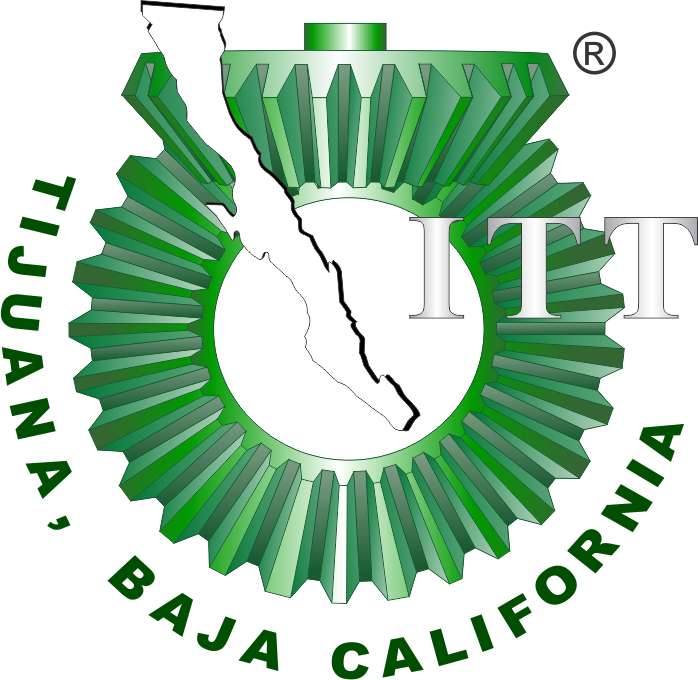

# Práctica 2: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

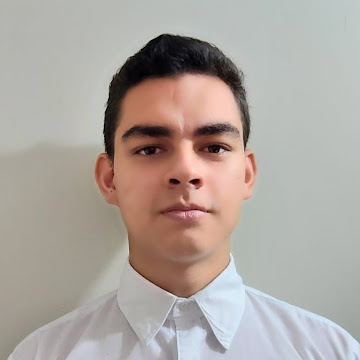

Nombre del alumno: **Aron Cervantes Armenta**

Número de control: **22211750**

Correo institucional: **l22211750@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

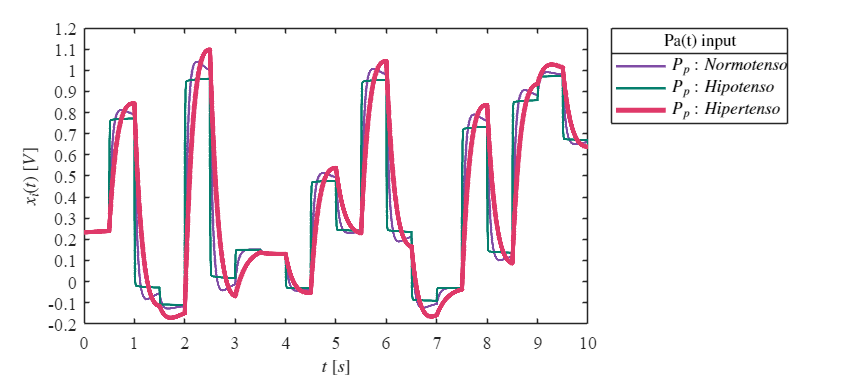

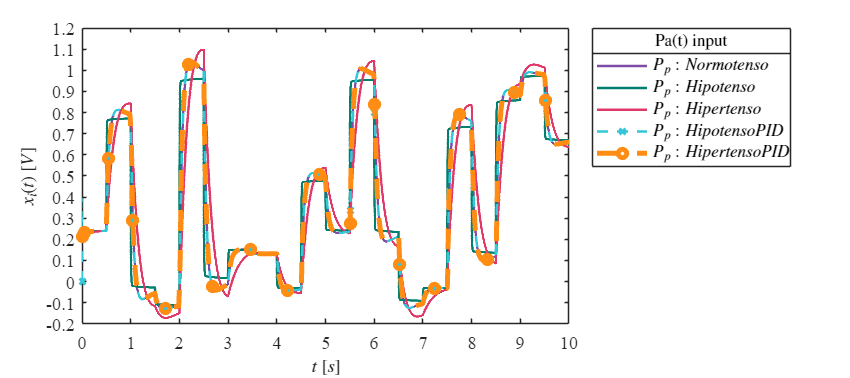

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23tb';
parameters.MaxStep = '1E-3';
set_param('Sistema/Pa(t)','Minimum','-0.2');
set_param('Sistema/Pa(t)','Maximum','1');
set_param('Sistema/Pa(t)','Seed','106');
set_param('Sistema/Pa(t)','SampleTime','0.5');
Signal = 'Pa(t)';
x = sim(file,parameters);
writematrix(x.Pa,'signal.xlsx')
plotsignals(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4,Signal)

## Funcion: Respuesta a las señales

function plotsignals(t,Pp0,Pp1,Pp2,Pp3,Pp4,Signal)

    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,2,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [127,76,165;
                5,127,109;
                223,57,105;
                51,199,216;
                255,141,20;
                123,45,67]/255;
    colororder(mycolors);

    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',3);
    L = legend('$P_{p}: Normotenso$','$P_{p}: Hipotenso$','$P_{p}: Hipertenso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],'FontSize',10);
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11);
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11);
    xlim([0,10]); xticks(0:1:10);
    if Signal == "Pa(t)"
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2);
    end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','Vector')


    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,2,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [127,76,165;
                5,127,109;
                223,57,105;
                51,199,216;
                255,141,20;
                123,45,67]/255;
    colororder(mycolors);

    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',t,Pp3,'--x',t,Pp4,'--o',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(5),'LineWidth',3);
    L = legend('$P_{p}: Normotenso$','$P_{p}: Hipotenso$','$P_{p}: Hipertenso$','$P_{p}: Hipotenso PID$','$P_{p}: Hipertenso PID$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],'FontSize',10);
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11);
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11);
    xlim([0,10]); xticks(0:1:10);
    if Signal == "Pa(t)"
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2);
    end

    exportgraphics(gcf,[Signal,'_PID.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'_PID.png'],'ContentType','Vector')

end